# Seminar 2

critical_values = readtable('multivariate_statistics/semi2/qq_plots_critical.csv');


function corr = retrieve_qq_critical(table, n, alpha)
    cols = [NaN 0.01 0.05 0.1]; % table is formatted this way to make it easier
    col = ismember(cols, alpha);
    if ~any(col)
        error 'Invalid confidence level. Allowed ones are {0.01, 0.05, 0.1}'
    end

    if any(ismember(table{:, 'n'}, n))
        % disp('Entry exists');
        corr = table{table{:, 'n'} == n, :}(col);
    elseif n > 300
        disp('Too large n. Will approximate to n=300');
        corr = table{table{:, 'n'} == 300, :}(col);
    else
        % disp('Entry does not exist, performing linear interpolation');
        lowerBound = table{table{:, 'n'} < n, :}(end,:);
        upperBound = table{table{:, 'n'} > n, :}(1,:);
        corr = linspace(lowerBound(col), upperBound(col), upperBound(1)-lowerBound(1));
        corr = corr(n-lowerBound(1)+1);
    end
end
% retrieve_qq_critical(critical_values, 300, 0.05)

## PROBLEM 13

File SM22_Seminar_2_Head_Brothers.xlsx contains measurements of the length and breadth of the heads of pairs of adult brothers in 25 randomly sampled families. We wish to analyze this dataset with techniques that assume multivariate Gaussianity:

% Importing from Seminar 1
function m = smean(pop)
    m = sum(pop, 1) / length(pop);
end

function s = sstd(pop)
    s = (pop-smean(pop))'*(pop-smean(pop)) / (length(pop)-1);
end

% Importing table
filename = 'multivariate_statistics/semi2/SM22_Seminar_2_Head_Brothers.xlsx';
% check that working directory is ME-2024
raw = readtable(filename);

### **a) Assess whether each of the 4 dimensions of these data is normally distributed.**

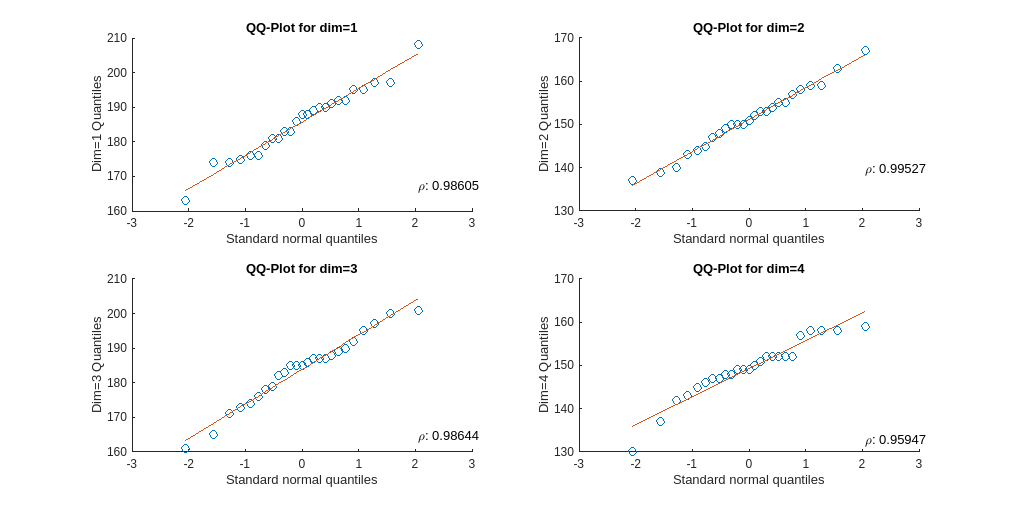

data = raw{:, 2:5};
alpha = 0.05;

corr = qq_plot(data);


disp(['With ' num2str(100*(1-alpha)) '% confidence level we can state that:']);

With 95% confidence level we can state that:


[n, p] = size(data);
for i=1:p
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We cannot reject that dimension ' num2str(i) ' follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' follows a normal distribution.'])
    end
end

We cannot reject that dimension 1 follows a normal distribution.
We cannot reject that dimension 2 follows a normal distribution.
We cannot reject that dimension 3 follows a normal distribution.
We cannot reject that dimension 4 follows a normal distribution.



function corr = correlation_coeff(data)
    % Get shape of the data
    n = size(data, 1);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);

    % Compute correlation coefficient
    num = q * (ordered_data - mean(ordered_data, 1));
    denom1 = diag((ordered_data - mean(ordered_data, 1))' * (ordered_data - mean(ordered_data, 1)))';
    denom2 = q * q';
    
    corr = num ./ sqrt(denom1 .* denom2);
end

function corr = qq_plot(data)
    % Get shape of the data
    [n, dims] = size(data);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);
    
    figure
    set(gcf,'position',[0,0,2000,1000]);

    corr = correlation_coeff(data);
    
    % Draw the corresponding QQ-Plots with regression line
    for i=1:dims
        % Create subplot
        subplot(ceil(sqrt(dims)),floor(sqrt(dims)), i);

        % Scatter plot and regression line in each axis
        scatter(q, ordered_data(:, i));
        hold on;
        b = [ones(n, 1) q']\ordered_data(:,i);
        ycalc = [ones(n, 1) q']*b;
        plot(q, ycalc);

        % Display correlation coefficient too
        y = (ordered_data(end,i)-ordered_data(1,i))*0.1 + ordered_data(1,i);
        text(q(end), y, ['\rho: ' num2str(corr(i))]);
        hold off;

        % Set title and labels for each axis
        title(['QQ-Plot for dim=' num2str(i)]);
        xlabel('Standard normal quantiles');
        ylabel(['Dim=' num2str(i) ' Quantiles']);
    end
end

### b) Assess whether each pair of dimensions is normally distributed.

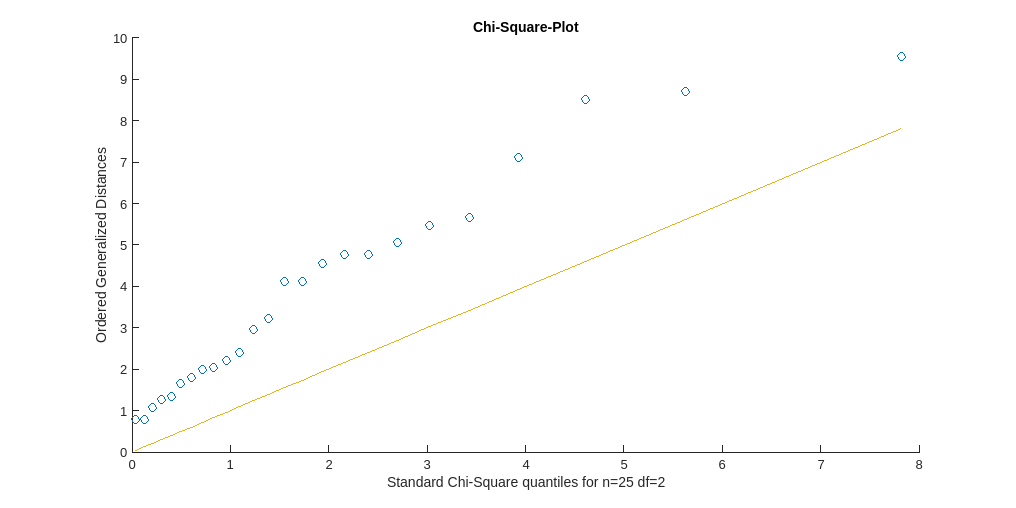

% QUESTION: can we just do chi-square plot with 2 degrees of freedom or
% we have to do 3d plot with 6 possible combinations and compute some kind
% of correlation coefficient? Because when df=2 looks quite bad, while with
% df=4 is almost perfect fit.
chi_square_plot(data, 2, alpha);


function d2 = generalized_squared_distances(data)
    x_bar = smean(data);
    S = sstd(data);
    d2 = diag((data - x_bar) / S * (data - x_bar)'); % / equivalent to * inv(S)
end

function chi_square_plot(data, df, alpha)
    % the p parameter is an integer in the range(2,n) that considers how
    % many variables are analyzed jointly
    % Get shape of the data
    n = size(data,1);
    
    % Order the squared distances
    d2 = sort(generalized_squared_distances(data));
    
    % Get standard chi-square quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = chi2inv(p, df);

    possible_outliers_logical = d2 > chi2inv(1-alpha, n);

    figure('Position',[0,0,2000,1000]);

    % Scatter plot and ideal slope
    scatter(q, d2');
    hold on;
    scatter(q(possible_outliers_logical), d2(possible_outliers_logical)', 'or');
    title('Chi-Square-Plot');
    ylabel('Ordered Generalized Distances');
    xlabel(['Standard Chi-Square quantiles for n=' num2str(n) ' df=' num2str(df)]);
    hold on;
    plot(q, q); % p184 it should have a slope of 1 for comparison
    hold off;
end

### c) Compute a chi-squared plot for all 4 dimensions considered together.

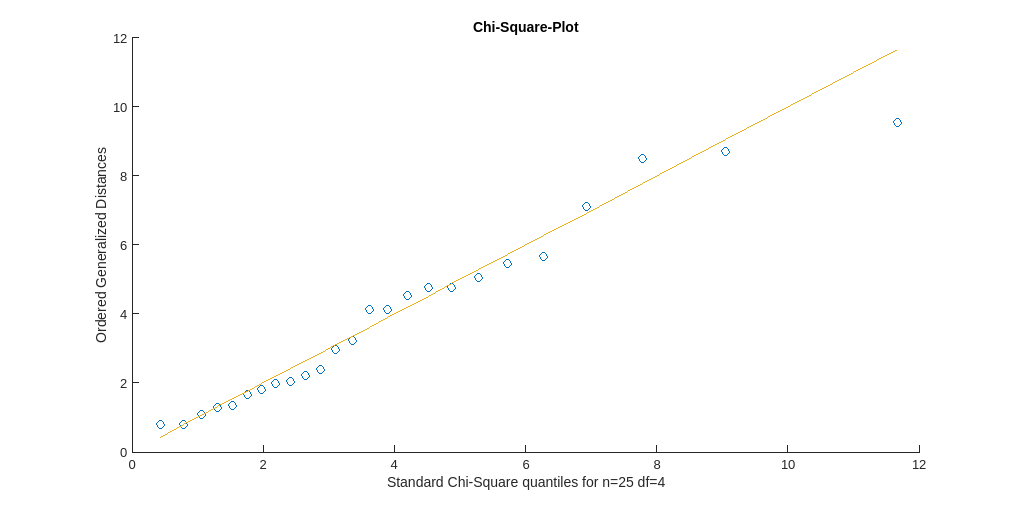

chi_square_plot(data,4, alpha);

### d) Identify possible outliers. If one or more outliers are found, concisely discuss what shall be done with it/them.

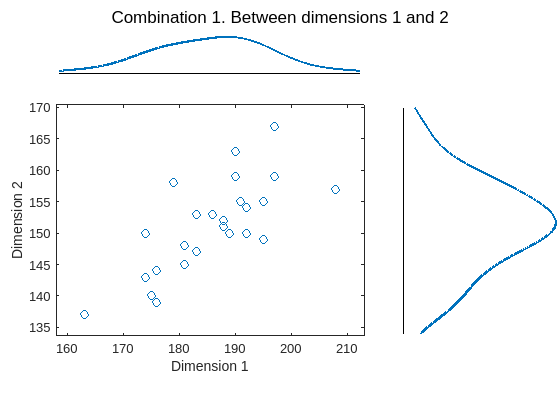

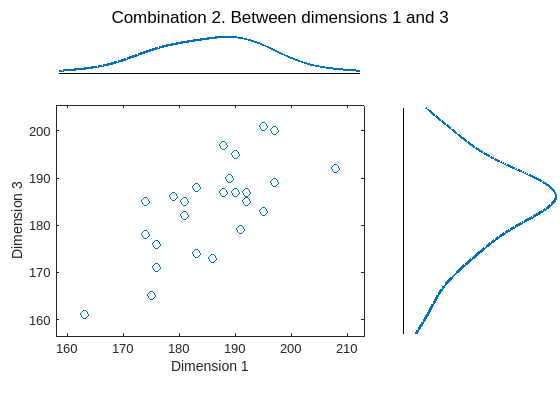

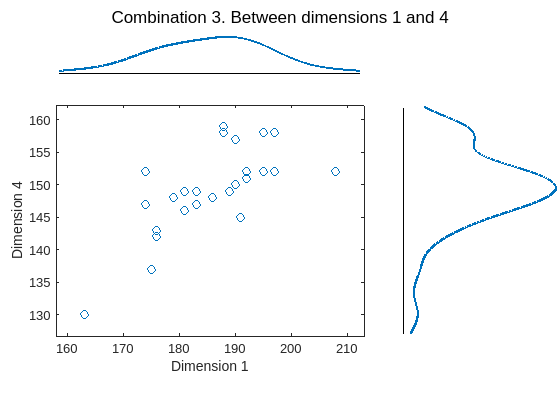

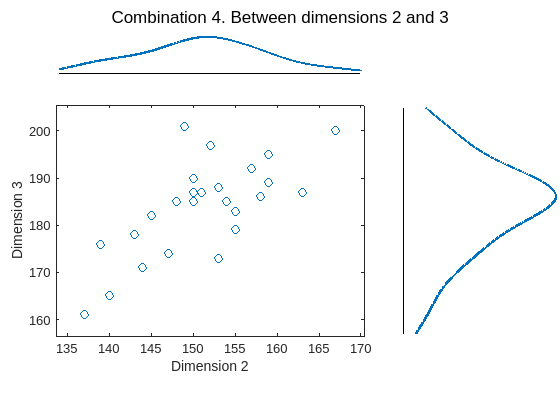

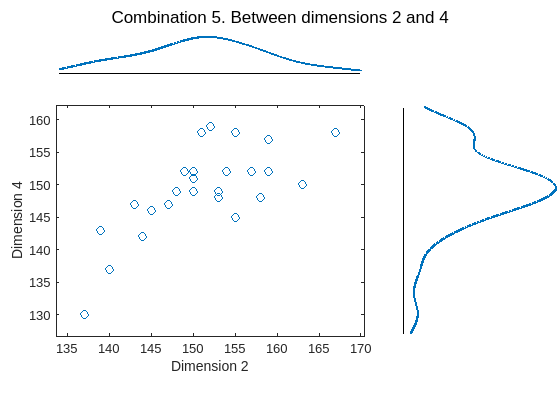

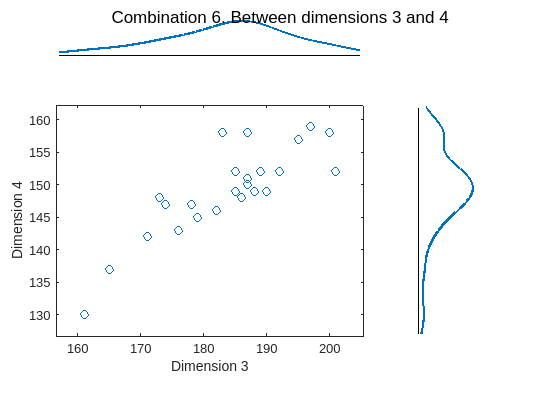

% Steps
% Make dot plot for each variable
[n, p] = size(data);
k = 1;
for i=1:p
    for j=i+1:p
        marginalscatter(data, i, j, ['Dimension ' num2str(i)], ['Dimension ' num2str(j)]);
        sgtitle(['Combination ' num2str(k) '. Between dimensions ' num2str(i) ' and ' num2str(j)]);
        k = k+1;
    end
end

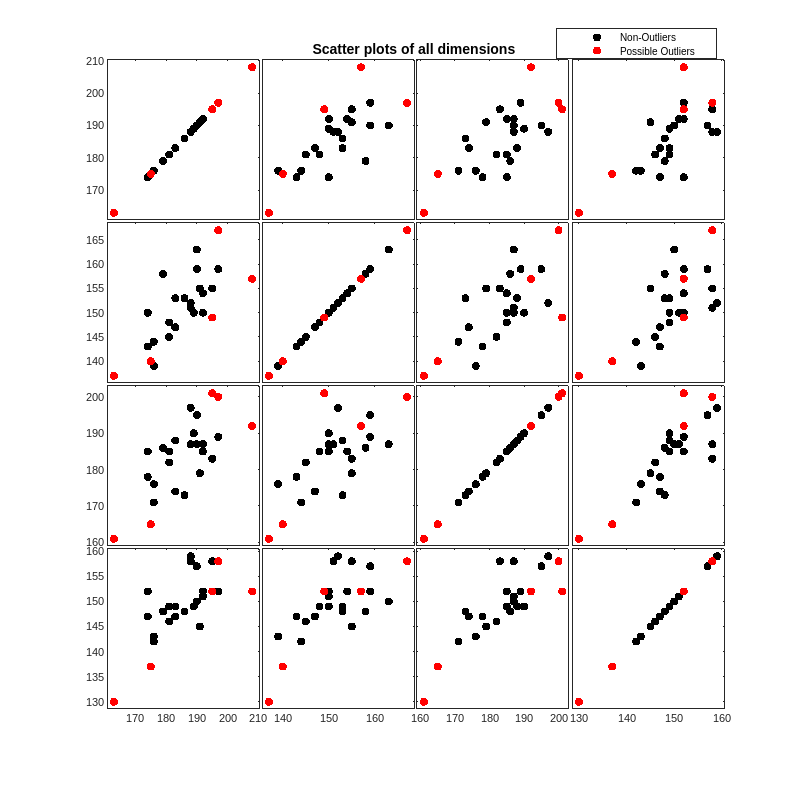


% Calculate and analyze standardized values (relative to size of dataset)
possible_outliers_logical_std = max(abs(standardize(data)) > abs(norminv(1-alpha)), [], 2);

% Make scatter plots for each pair of variables
figure('Position', [100 100 1000 1000]);
gplotmatrix(data, data, possible_outliers_logical_std, ['k', 'r']);
h = findobj('Tag','legend');
set(h(1), 'String', {'Non-Outliers', 'Possible Outliers'}, 'Position', [0.7155 0.9282 0.1600, 0.0331]);
title('Scatter plots of all dimensions');


% Examine high values in chi-squared plot
possible_outliers_logical_chi = generalized_squared_distances(data) > chi2inv(1-alpha, n);
disp(possible_outliers_logical_chi');

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0




function h = marginalscatter(data, dim1, dim2, xlabel, ylabel)
    figure;
    h = scatterhist(data(:,dim1), data(:,dim2), 'kernel', 'on', 'Location', 'NorthEast', 'Direction', 'out');
    
    h(2).Position = h(2).Position .* [1 1 1 0.4];
    h(3).Position = h(3).Position .* [1 1 0.4 1];
    h(1).Position(2) = h(1).Position(2) + 0.1;
    h(2).Position(2) = h(2).Position(2) + 0.1;
    h(3).Position(2) = h(3).Position(2) + 0.1;

    h(1).YAxisLocation = 'left';
    h(1).XAxisLocation = 'bottom';
    h(1).XLabel.String = xlabel;
    h(1).YLabel.String = ylabel;
end

function z = standardize(data)
    s = sstd(data);
    z = (data - mean(data)) ./ sqrt(diag(s))';
end

### e) Based on all the above information, indicate whether you would find it acceptable to test this dataset using statistical techniques that assume the data following an (approximately) multivariate normal distribution. Make a clear and concise justification of your answer.

Yes, even though there are some noticeable outliers they are not significant overall.

## PROBLEM 14

File SM22_Seminar_2_Alcohol_and_Tobacco.xlsx contains data from 200 cases of oesophageal cancer and 775 controls. For each subject, the table provides his/her alcohol and tobacco consumption, indicated in grams per day. We want to test whether the average alcohol and tobacco consumption (combined as bivariate samples) are significantly higher in subjects that developed oesophageal cancer than they are in controls.

### a) State the null and alternative hypotheses to be tested (make sure to include the mathematical formulation).


$$\begin{cases}
      H_{0}: \mu_{AT} = \mu_{C}\\
      H_{A}: \mu_{AT} \ne \mu_{C}\\
\end{cases}
\text{ , where } \mu_{AT} \text{ is the average of the Alcohol and Tobacco group}
\text{ and } \mu_{C} \text{ is the average of the Control group}$$


### b) Inspect your data for multivariate normality. Clearly indicate whether you would advise in favor or against using statistical methods that assume multivariate normality in these data.

% Importing table
filename = 'multivariate_statistics/semi2/SM22_Seminar_2_Alcohol_and_Tobacco.xlsx';
% check that working directory is ME-2024
raw = readtable(filename);

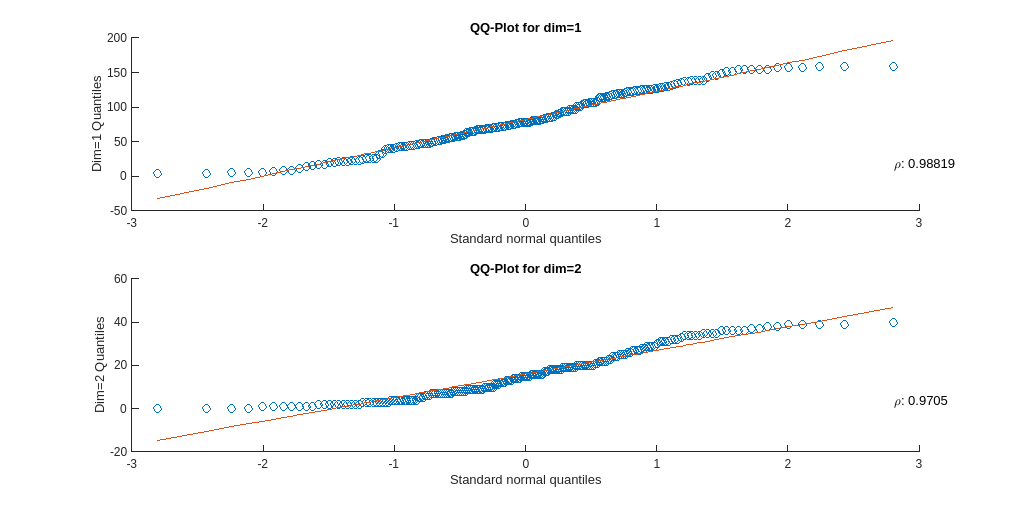

pop_full = raw{:, [2,3]};
pop_cancer = raw{raw{:,'OesophCancer'} == 1, [2,3]};
pop_noCancer = raw{raw{:,'OesophCancer'} == 0, [2,3]};

alpha = 0.05;
[n, p] = size(pop_cancer);
corr = qq_plot(pop_cancer);

for i=1:p
    % disp([corr(i, j) retrieve_qq_critical(critical_values, sizes(i), alpha)]);
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We cannot reject that dimension ' num2str(i) ' of the population with cancer follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' of the population with cancer follows a normal distribution.'])
    end
end

We can reject that dimension 1 of the population with cancer follows a normal distribution.
We can reject that dimension 2 of the population with cancer follows a normal distribution.


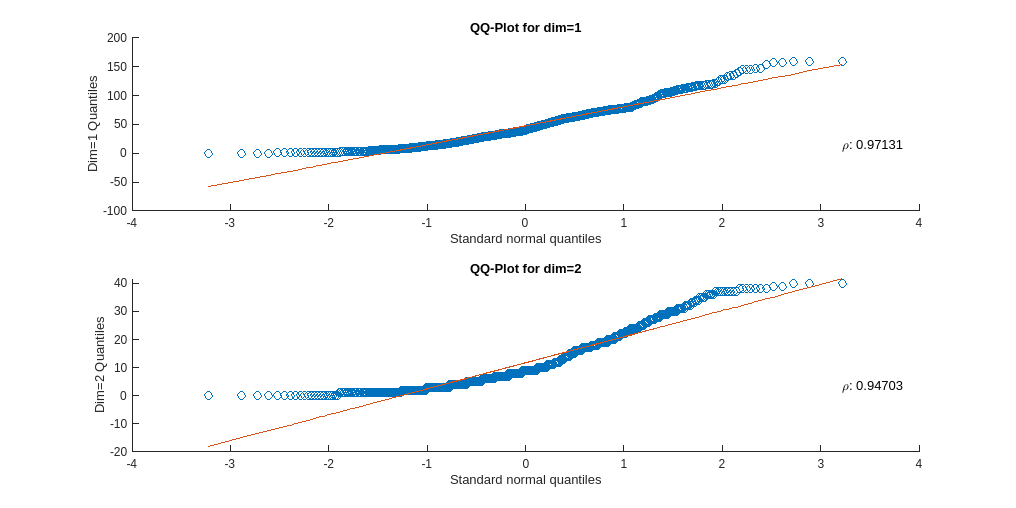

[n, p] = size(pop_noCancer);
corr = qq_plot(pop_noCancer);

for i=1:p
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We cannot reject that dimension ' num2str(i) ' of the population without cancer follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' of the population without cancer follows a normal distribution.'])
    end
end

Too large n. Will approximate to n=300


We can reject that dimension 1 of the population without cancer follows a normal distribution.


Too large n. Will approximate to n=300


We can reject that dimension 2 of the population without cancer follows a normal distribution.


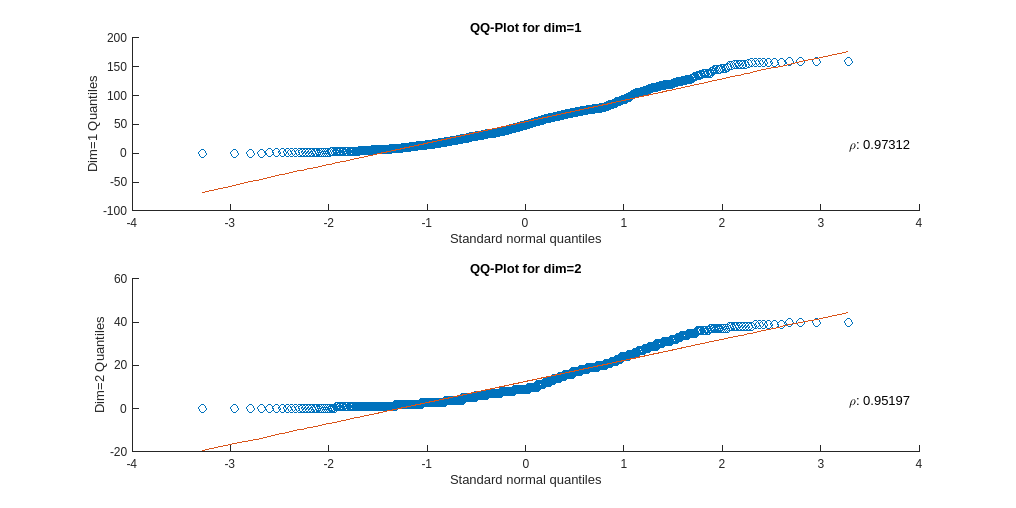

[n, p] = size(pop_full);
corr = qq_plot(pop_full);

for i=1:p
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We cannot reject that dimension ' num2str(i) ' of the full population follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' of the full population follows a normal distribution.'])
    end
end

Too large n. Will approximate to n=300


We can reject that dimension 1 of the full population follows a normal distribution.


Too large n. Will approximate to n=300


We can reject that dimension 2 of the full population follows a normal distribution.


I would not assume univariate normality for the population that has not developed oesophageal cancer.

### c) Based on your conclusions in (b), test the hypotheses stated in (a) at significance level α = 0.05. Indicate what conclusion you reach.

We cannot proceed because we cannot assume univariate (thus, multivariate too) normality for the second group.

### d) Calculate and plot a 95% confidence region for the difference of (alcohol, tobacco) consumption between cancer cases and controls. Show that it conforms with the conclusion in (c).

We cannot proceed (strange).

## PROBLEM 15

File SM22_Seminar_2_Height_and_Weight.xlsx contains data from men and women engaged in regular exercise. Each subject was asked to self-report his/her height and weight. Actual values of height and weight were also measured. We are interested in the following question: on average, do men and women differ in the bias with which they perceive their body height and weight (considered jointly)?

### a) Inspect the data and discuss what dimensions shall be used and in what manner (e.g. as provided, added, multiplied, ...). State the appropriate null and alternative hypotheses.


$$\begin{cases}
      H_{0}: \delta_{M} = \delta_{F}\\
      H_{A}: \delta_{M} \ne \delta_{F}\\
\end{cases}
\text{ , where } \delta_{M} \text{ is the difference of Reported and Perceived measurements of Males}
\text{ and } \delta_{F} \text{ is the difference of Reported and Perceived measurements of Females}$$


% Importing table
filename = 'multivariate_statistics/semi2/SM22_Seminar_2_Height_and_Weight.xlsx';
% check that working directory is ME-2024
raw = readtable(filename);

% bivariate repeated measurements ???
% reported - perceived
pop_full = raw{:, 2:5};
pop_male = pop_full(raw{:, "sex_1_M_2_F_"} == 1, :);
pop_female = pop_full(raw{:, "sex_1_M_2_F_"} == 2, :);
D_male = [pop_male(:, 4) - pop_male(:, 2), pop_male(:, 3) - pop_male(:, 1)];
D_female = [pop_female(:, 4) - pop_female(:, 2), pop_female(:, 3) - pop_female(:, 1)];

### b) Assess whether your data (or the relevant subsets) can be analyzed under the assumption of multivariate normality. If you find that this is not the case, propose and implement some solution. Carefully justify your choice.

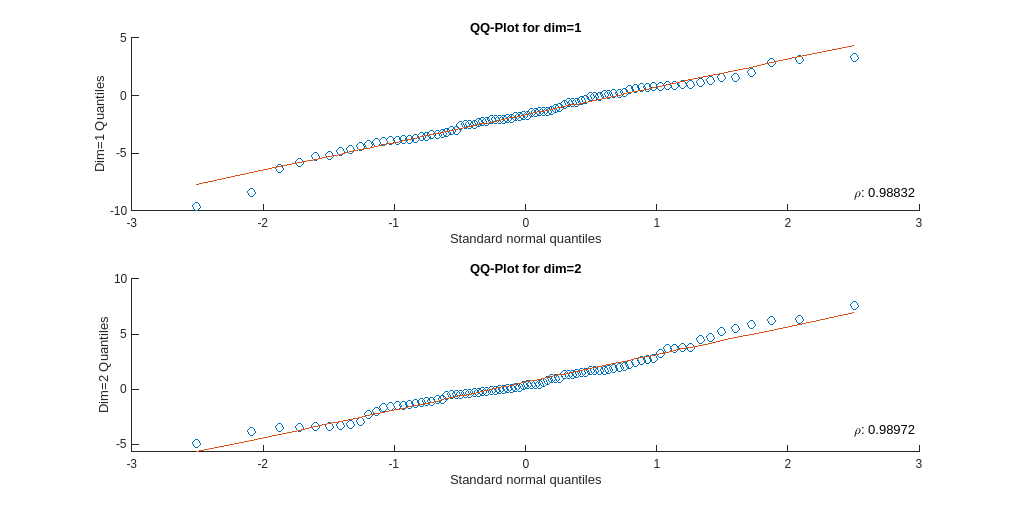

[n, p] = size(D_male);
corr = qq_plot(D_male);

for i=1:p
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We cannot reject that dimension ' num2str(i) ' of the male population follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' of the male population follows a normal distribution.'])
    end
end

We cannot reject that dimension 1 of the male population follows a normal distribution.
We cannot reject that dimension 2 of the male population follows a normal distribution.


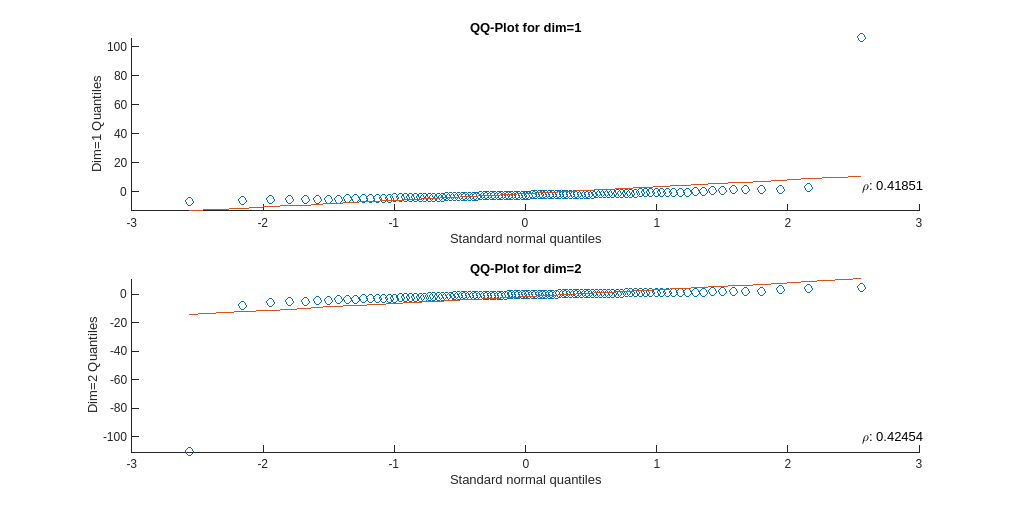

[n, p] = size(D_female);
corr = qq_plot(D_female);

As of right now, we cannot assume univariate normality for the female population. We can see some outliers in the data, so we could remove those.

for i=1:p
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We cannot reject that dimension ' num2str(i) ' of the female population follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' of the female population follows a normal distribution.'])
    end
end

We can reject that dimension 1 of the female population follows a normal distribution.
We can reject that dimension 2 of the female population follows a normal distribution.


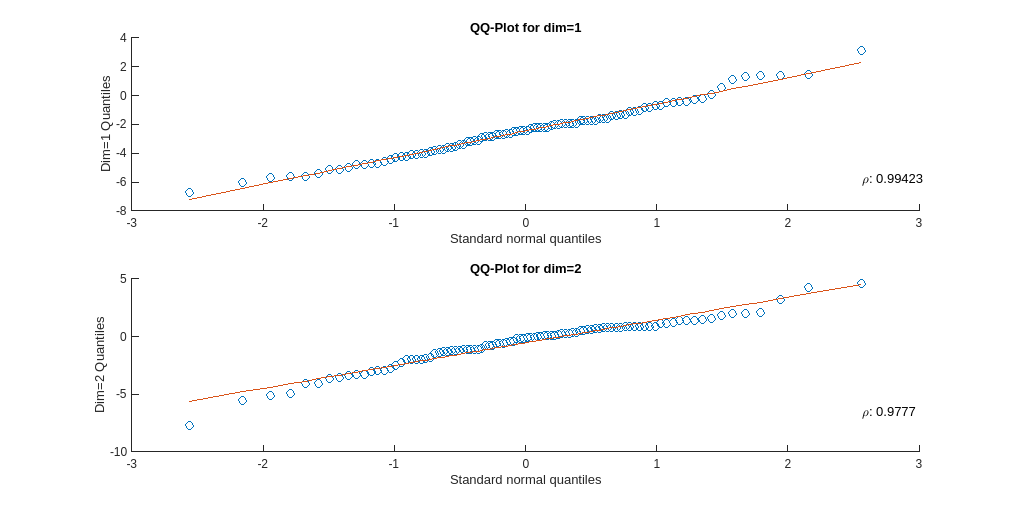

c = 1; % increase outlier detection severity
idx = standardize(D_female) <= norminv(1-alpha*c);
idx = logical(idx(:,1) .* idx(:,2)); % remove datapoint if any of the two dimensions is outlier
D_female = D_female(idx, :);

[n, p] = size(D_female);
corr = qq_plot(D_female);

for i=1:p
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We cannot reject that dimension ' num2str(i) ' of the female population follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' of the female population follows a normal distribution.'])
    end
end

We cannot reject that dimension 1 of the female population follows a normal distribution.


We can reject that dimension 2 of the female population follows a normal distribution.


Now we can assess multivariate normality since we cannot reject univariate normality.

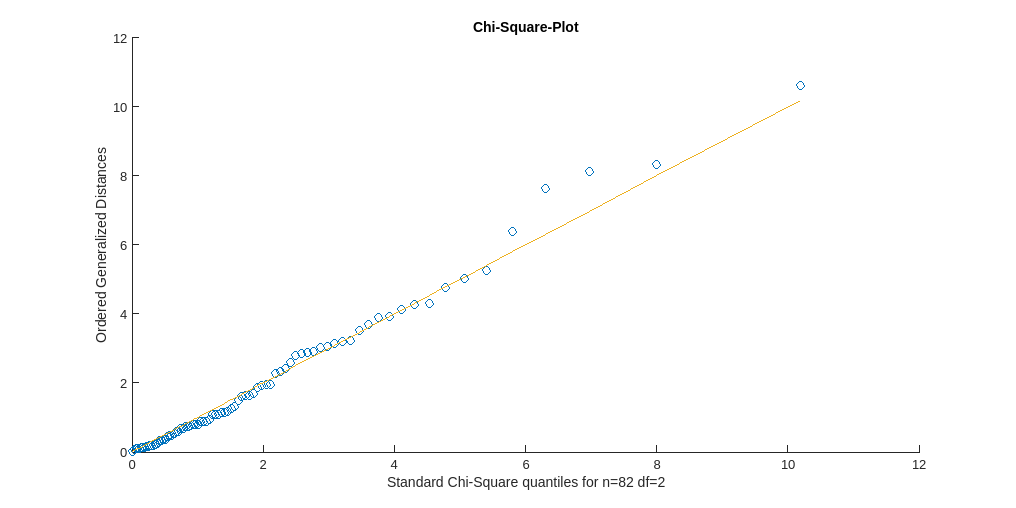

chi_square_plot(D_male, 2, alpha);

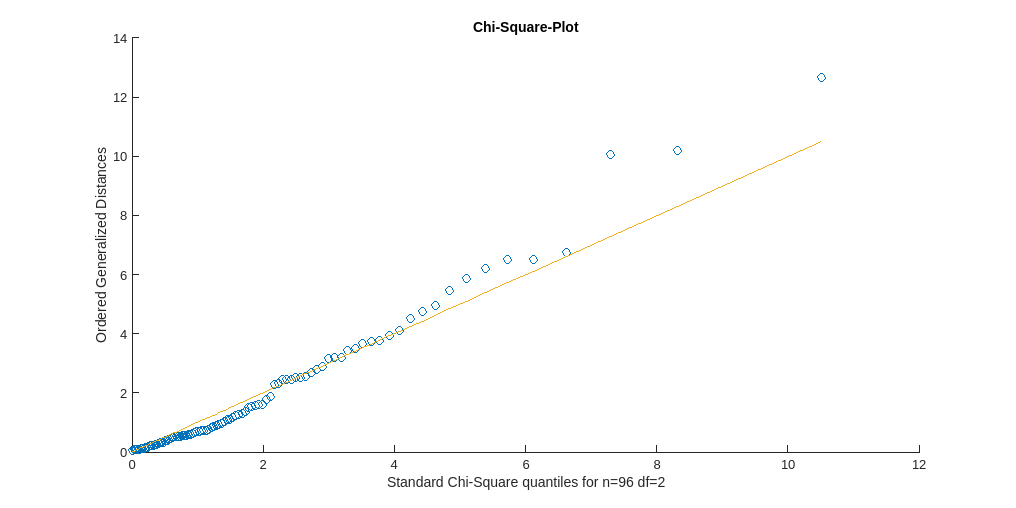

chi_square_plot(D_female, 2, alpha);

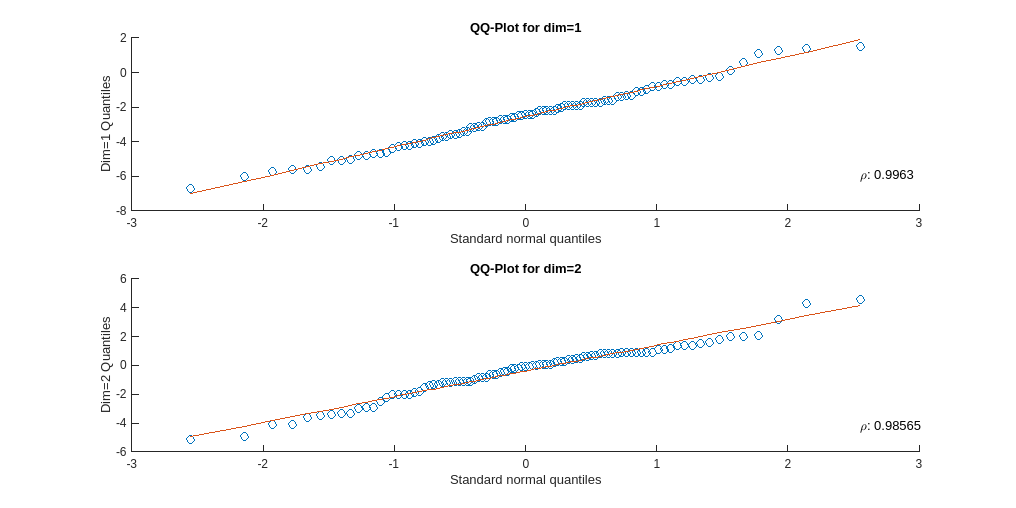

D_female = D_female(generalized_squared_distances(D_female) <= 9,:);
[n, p] = size(D_female);
corr = qq_plot(D_female);

for i=1:p
    if corr(i) > retrieve_qq_critical(critical_values, n, alpha)
        disp(['We cannot reject that dimension ' num2str(i) ' of the female population follows a normal distribution.'])
    else
        disp(['We can reject that dimension ' num2str(i) ' of the female population follows a normal distribution.'])
    end
end

We cannot reject that dimension 1 of the female population follows a normal distribution.


We can reject that dimension 2 of the female population follows a normal distribution.


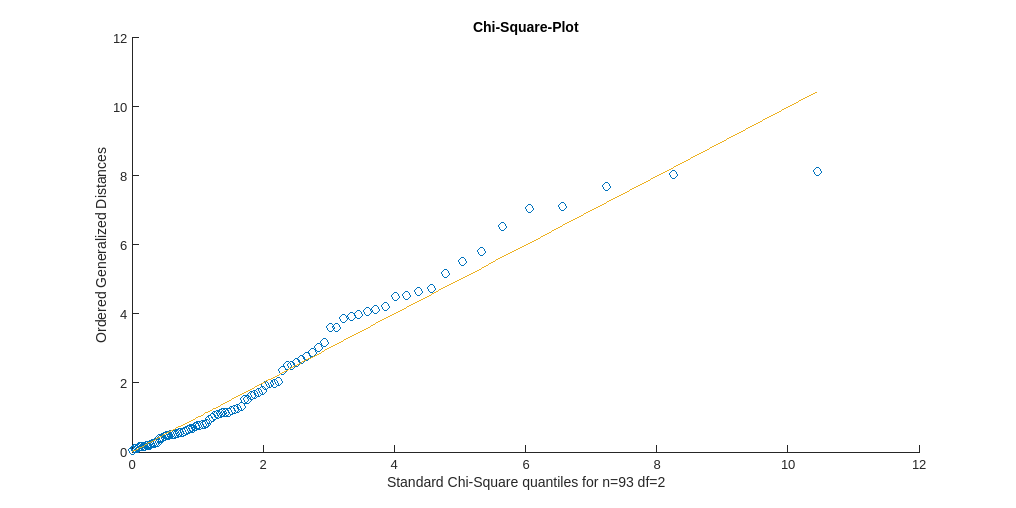

chi_square_plot(D_female, 2, alpha)

### c) Test the null hypothesis at significance level α = 0.05. Clearly indicate and justify the statistic you choose. Indicate your conclusion.

% independent T² test for large n
[n1, p] = size(D_male);
n2 = size(D_female, 1);
x_bar = smean(D_male) - smean(D_female);
cov_mat = (1/n1 * sstd(D_male) + 1/n2 * sstd(D_female));
T2_hat = x_bar / cov_mat * x_bar';
df1 = p;
df2 = (n1 + n2 - p - 1);
F_crit = (n1 + n2 - 2) * df1 / (n1 + n2 - df1 - 1) * finv(1-alpha, df1, df2);
if T2_hat < F_crit
    disp('We cannot reject the null hypothesis >> There is no significant difference in one dimension');
else
    disp('We can reject the null hypothesis >> There is a significant difference');
end

We can reject the null hypothesis >> There is a significant difference


### d) Compute 95% confidence intervals for the bias in perceived height and for the bias in perceived weight. Since we are analyzing multivariate data, the intervals should hold simultaneously at the specified confidence level.

ci = CI_multivariate(x_bar, cov_mat, F_crit) % rows are dimensions (height, weight), columns are lower and upper bound

ci =     0.0779    1.6841
    0.1804    1.8559


axis = ellipsis_axis_multivariate(cov_mat, F_crit)

axis =    -0.7046    0.3854
    0.3587    0.7571


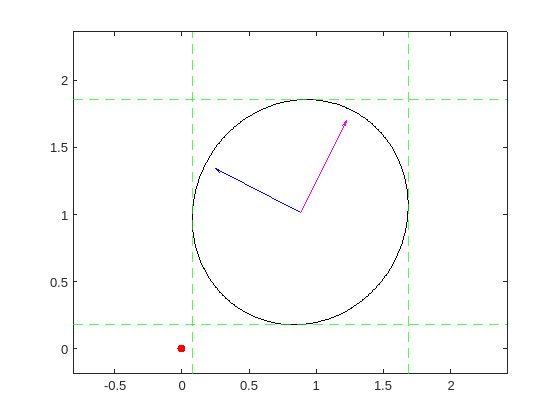

draw_region_CI(x_bar, cov_mat, F_crit)
xlim([-0.81 2.42]);
ylim([-0.18 2.36]);

function ci = CI_multivariate(x_bar, cov_mat, c2)
    ci = [x_bar' - sqrt(c2 * diag(cov_mat)), x_bar' + sqrt(c2 * diag(cov_mat))];
end

function ax = ellipsis_axis_multivariate(cov_mat, c2)
    [evec, eval] = eig(cov_mat);
    eval = diag(eval);
    ax = sqrt(c2 * eval)' .* evec;
end

function draw_region_CI(x_bar, cov_mat, c2)
    ax = ellipsis_axis_multivariate(cov_mat, c2);
    t = -pi:0.01:pi;
    circle = [cos(t)', sin(t)'];
    ellipsis = x_bar + circle * ax';

    figure
    plot(ellipsis(:,1), ellipsis(:,2), 'k');
    hold on;
    quiver(x_bar(1), x_bar(2), ax(1,1), ax(2,1), 'b');
    quiver(x_bar(1), x_bar(2), ax(1,2), ax(2,2), 'm');
    
    ci = CI_multivariate(x_bar, cov_mat, c2);
    xline(ci(1,1), '--g');
    xline(ci(1,2), '--g');
    yline(ci(2,1), '--g');
    yline(ci(2,2), '--g');

    scatter(0, 0, 'or', 'filled');
    hold off;
    axis equal;
end

## PROBLEM 16

Given the 4-dimensional random sample from file SM22_Seminar_2_4d.xlsx, inspect the data to determine if it follows a multivariate normal distribution.

### a) Indicate graphically if each of the dimensions is normally distributed.

### b) Indicate graphically if each pair of dimensions is normally distributed.

### c) Compute Q-Q plots for each dimension.

### d) Compute a chi-squared plot for all dimensions considered together.

### e) Use the above plots to look for outliers.

### f) Based on all the above information, indicate whether you would find acceptable to test this dataset using statistical techniques that assume the data following an (approximately) multi-variate normal distribution.

## PROBLEM 17

File SM22_Seminar_2_Plants.xlsx contains data samples from 2 types of plants. Each row of the file contains one sample, for which there are 5 columns, as follows: i) type of plant (1 or 2); ii) sepal length; iii) sepal width; iv) petal length; v) petal width. We want to test if the two types of plants have different mean in terms of these 4 variables that have been measured, using Hotelling’s T².

### a) State the null and alternative hypotheses to be tested.

### b) Inspect the data and indicate whether it fulfills the assumptions necessary to use Hotelling’s T² (independence of the random samples can be assumed).

#### b1. Test the assumptions of multivariate normality.

#### b2. Inspect (roughly) the assumption of equality of covariances.

### c) Based on your conclusions in (b), determine if any of the T² statistics discussed in class could be employed to test the hypotheses in (a). Hint: If none is suitable, try transforming one or more variables. If you cannot find a satisfactory transformation, you can remove the dimension(s) that prevent your data from meeting the assumptions required to apply Hotelling’s T².

### d) Test the hypothesis indicated in (a) at α = 0.05 significance level and indicate what is the conclusion.